load name_ting.mat
yn = y(:,2);
T  = 60;  % physical connection, 60 for 60 seconds

N  = length(yn);
n  = 0:N-1

n =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


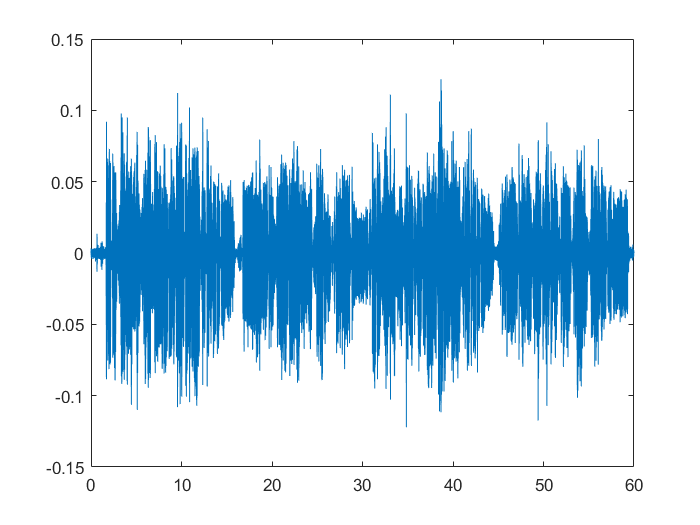

xn = T*n/N;
plot(xn,yn)

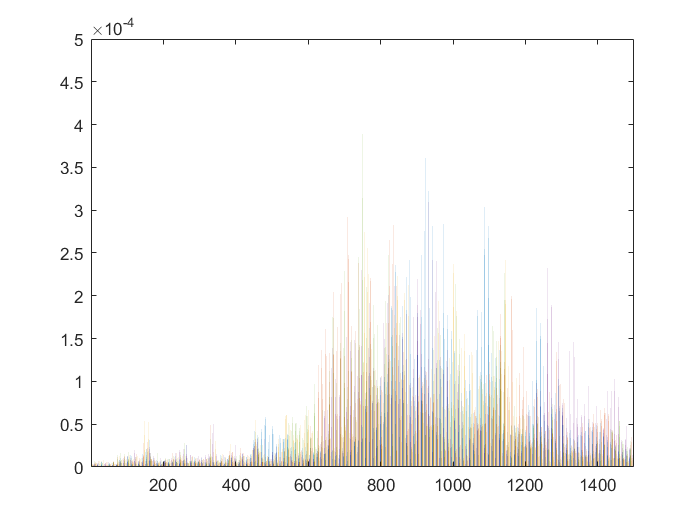

SampleRate = 44100;
delta_t = 0.2;
t = 0:delta_t:T;

z  = [];
for j = 1:length(t)-1
    yt = yn(xn >= t(j) & xn <= t(j+1));
    Nt = length(yt);
    Tmax = Nt/SampleRate;
    c = fft(yt);
    BandMax = 1500;  % 200 BPM,  1500Hz
    k = 1:(BandMax*Tmax);  % N/2 for all spectrum  % only meaningful range
    Hz = k/Tmax;           % (1:200)*3/3=1:200   (1:(200*3))/3 = 1/3, 2/3, 1, 4/3, ...
    z(:,j) = abs(c(k+1))/(N/2); % c(1) = a0*N, c(2) = (a1-ib1)*N/2,..
    %z(N/2) = z(N/2)/2;    % c(N/2+1) = N*a_N/2
    bar(Hz,z);
end

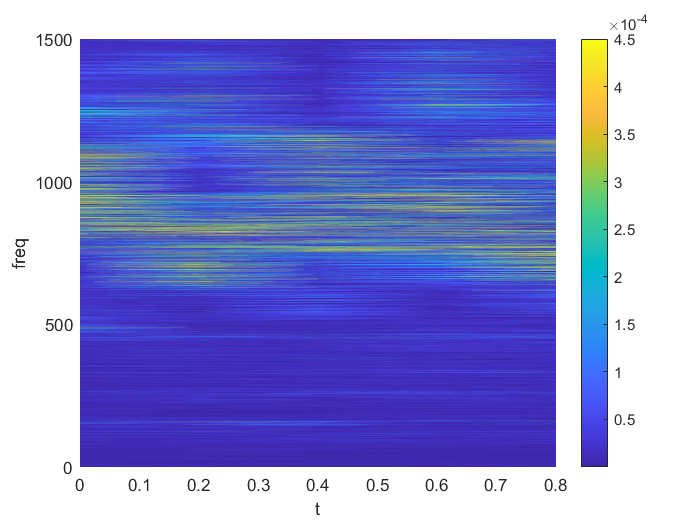

surf(t(1:end-1),Hz,z)
view(2)
xlabel('t');
ylabel('freq');
shading interp;
colorbar